### Probabilistic Road Map Planner

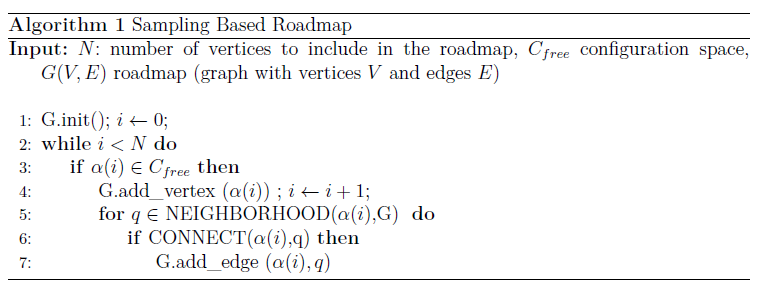

1) Load map files from ${\tt exampleMaps.mat}$ contained in maps.zip. The file contains a simple and a more complex map represented by a binary occupancy grid (logical (binary) matrix) in which an entry of $1$ indicates an occupied and $0$ an unoccupied cell in the environment. Convert the maps into binary occupancy grids, generate and visualize a probabilistic roadmap for the environment.

load exampleMaps.mat

2) The method ${\tt binaryOccupancyMap}$ generates a 2-D occupancy grid object, which partitions the environment into free space and obstacles. The occupancy grid is constructed either from map data or sensor data in conjunction with robot pose estimates.

creates a grid from the binary entries in matrix ${\tt p}$ at a resolution ${\tt res}$ specified in cells per meter. Notice, that this differs from the definition in YAML-files which define the resolution w.r.t. meter / pixel (cell). The resolution and the dimension of the binary matrix ${\tt p} $ determine the height and width of the occupancy grid. Generate the occupancy grids from the map data with a resolution of $$2\frac{\mathrm{cells}}{\mathrm{m}}$$. Visualize both occupancy grids with ${\tt show}$.

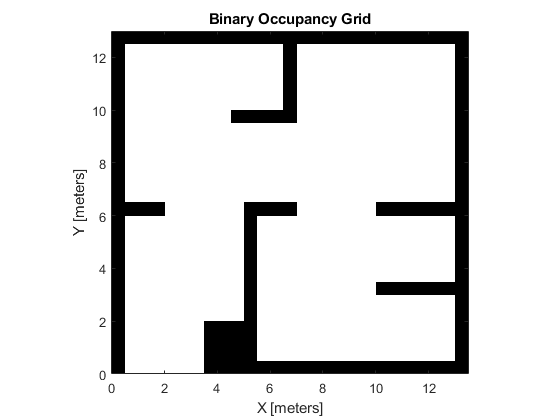

map_simple = binaryOccupancyMap(simpleMap, 2);
map_complex = binaryOccupancyMap(complexMap, 2);
show(map_simple)

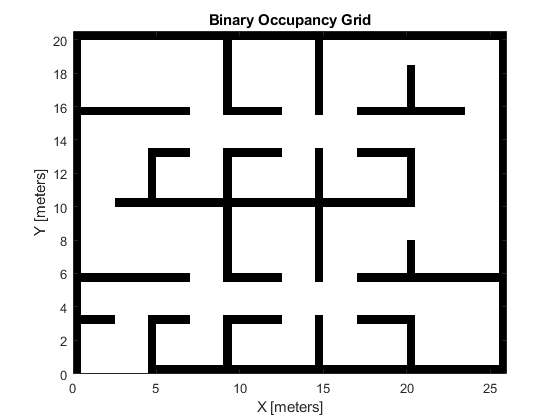

show(map_complex)

3) Generate a probabilistic roadmap for the simple map with $50$ nodes. ${\tt mobileRobotPRM(map,numnodes)} $creates a roadmap from the binary occupancy grid ${\tt map}$, with the maximum number of nodes ${\tt numnodes}$. Visualize the road map with ${\tt show}$.

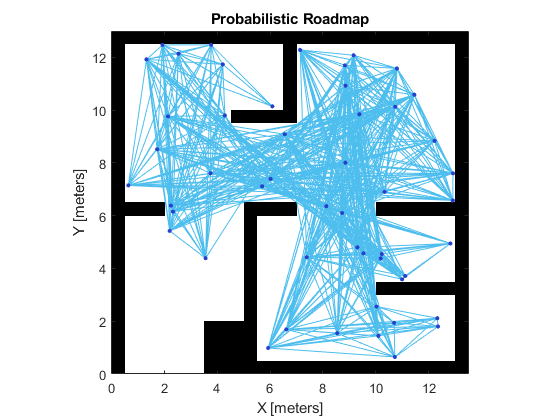

simple_roadmap = mobileRobotPRM(map_simple, 50);
show(simple_roadmap)

4) Generate a denser probabilistic roadmap for the larger and more complex map with $500$ nodes. Visualize the road map with ${\tt show}$.

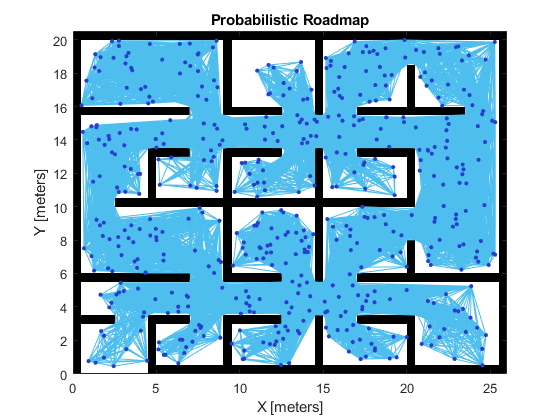

complex_roadmap = mobileRobotPRM(map_complex, 500);
show(complex_roadmap)

5) Plan a collision-free path from start location $$\mathbf{x}_s=[2,1]$$ to goal location $$\mathbf{x}_g=[12,10]$$ for the simple map using ${\tt findpath}$ and visualize the roadmap and path with ${\tt show}$.

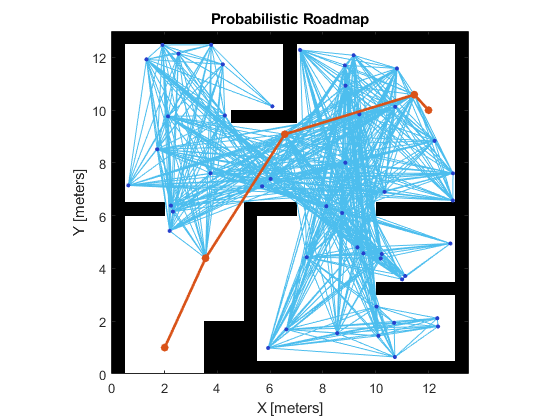

start_loc_simple = [2 1];
goal_loc_simple = [12 10];
simple_path = findpath(simple_roadmap, start_loc_simple, goal_loc_simple);
show(simple_roadmap)

6) Plan a collision-free path from start location $$\mathbf{x}_s=[2,1]$$ to goal location $$\mathbf{x}_g=[22,18]$$  for the complex map. Visualize the roadmap and path.

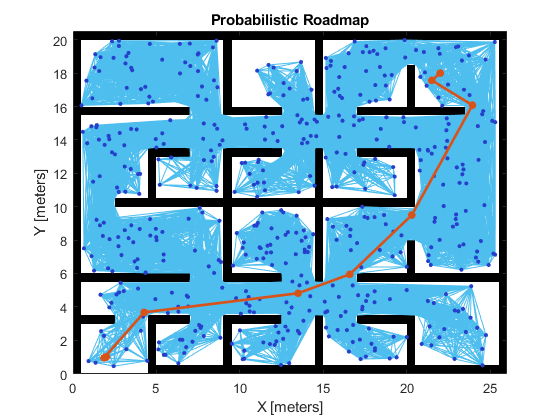

start_loc_complex = [2 1];
goal_loc_complex = [22 18];
complex_path = findpath(complex_roadmap, start_loc_complex, goal_loc_complex);
show(complex_roadmap)

7) Load the TurtleBot3 map from the image file ${\tt turtlebot3world.pgm}$ using

Generate the corresponding binary occupancy grid. Notice that a resolution of $$20$$ cells per meter corresponds to $$0.05$$ meter per pixel in PGM file. Reduce the map to the relevant area. Also consider to adapt the origin of the coordinate system in the binary occupancy grid properly. Use the property ${\tt GridLocationInWorld}$ of the ${\tt binaryOccupancyMap}$ object.

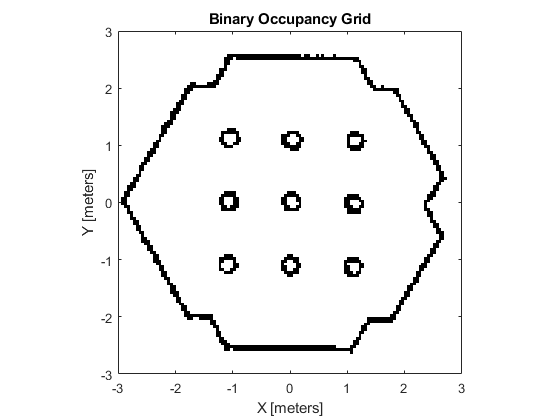

turtlebot3world = ~logical(imread('turtlebot3world.pgm'));
turtle_map = binaryOccupancyMap(turtlebot3world, 20);
turtle_map.GridLocationInWorld = [-10 -10];
ax = gca;
ax.XLim = [-3 3];
ax.YLim = [-3 3];

8) Start the Turtlebot3 Gazebo simulation by running the command

in a Linux terminal.

9) Plan and visualize a path that connects the robot's current location with the goal location $$\mathbf{x}_g= [0,2]$$ with the probabilistic road map planner in Matlab. For this, query from topic ${\tt odom}$ and use the helper function ${\tt OdometryMsg2Pose}$ to obtain the current robot pose.

rosshutdown

Shutting down global node /matlab_global_node_20139 with NodeURI http://192.168.2.111:53204/


rosinit('http://ubuntu:11311/')

Initializing global node /matlab_global_node_03469 with NodeURI http://192.168.2.111:53221/


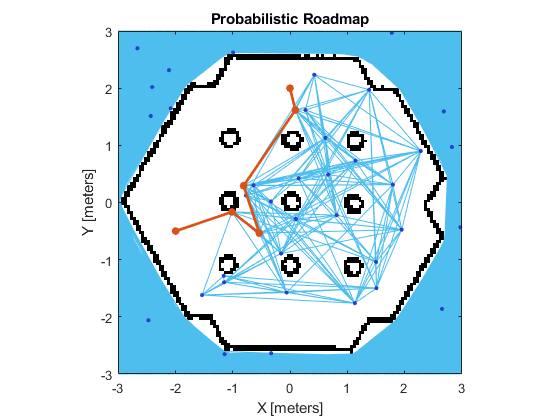

odomSub = rossubscriber('/odom');
odomMsg = receive(odomSub);
[x_odom, y_odom, ~] = OdometryMsg2Pose(odomMsg);

turtle_roadmap1 = mobileRobotPRM(turtle_map, 500);
start_loc_turtle = [x_odom y_odom];
goal_loc_turtle = [0 2];
turtle_path1 = findpath(turtle_roadmap1, start_loc_turtle, goal_loc_turtle);
show(turtle_roadmap1)
ax = gca;
ax.XLim = [-3 3];
ax.YLim = [-3 3];

10) Launch RViz by running the command

in a Linux terminal. 

11) Query the goal pose from the topic ${\tt /move\_base\_simple/goal}$ rather than using a fixed goal pose. Use the helper function ${\tt PoseStampedMsg2Pose}$ to convert the ROS message. Plan and visualize the path for the new custom goal location.

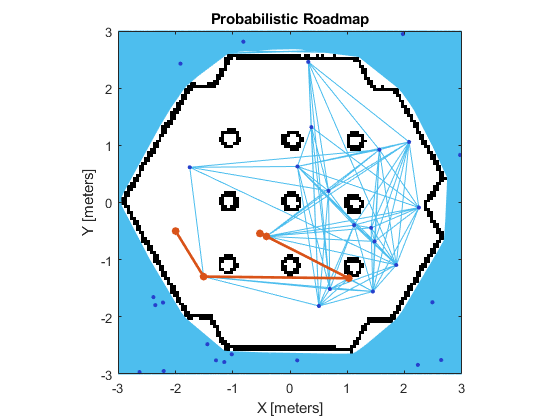

navGoalSub = rossubscriber('/move_base_simple/goal');
navGoalMsg = receive(navGoalSub, 20);

odomSub = rossubscriber('/odom');
odomMsg = receive(odomSub);

[x_odom, y_odom, ~] = OdometryMsg2Pose(odomMsg);
[x_goal, y_goal, ~] = PoseStampedMsg2Pose(navGoalMsg);

turtle_roadmap2 = mobileRobotPRM(turtle_map, 500);
start_loc_turtle = [x_odom y_odom];
goal_loc_turtle = [x_goal y_goal];
turtle_path2 = findpath(turtle_roadmap2, start_loc_turtle, goal_loc_turtle);
show(turtle_roadmap2)
ax = gca;
ax.XLim = [-3 3];
ax.YLim = [-3 3];

12) Notice that currently the planned path does not consider the dimensions of the circular robot and that some vertices of the roadmap are close to obstacles. To plan a safe and collision-free path inflate the occupancy grid by the robot radius. The function ${\tt inflate(map,radius)}$ enlarges occupied map cells by the specified radius. The status of free cells separated to an occupied cell by less than the radius changes to occupied (true). Inflate the world occupancy grid by the robot radius $$r=0.18\,\mathrm{m}$$ plus a safety margin $$d=0.12\,\mathrm{m}$$. Regenerate the roadmap for the world environment and replan the path.

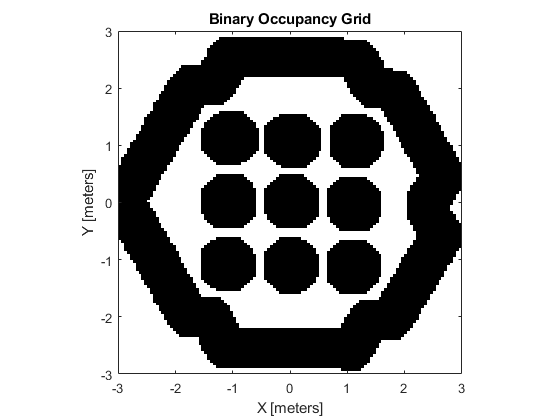

turtlebot3world = ~logical(imread('turtlebot3world.pgm'));
turtle_map = binaryOccupancyMap(turtlebot3world, 20);

radius = 0.18;
safety_margin = 0.12;
inflate(turtle_map, radius + safety_margin);
turtle_map.GridLocationInWorld = [-10 -10];
show(turtle_map)
ax = gca;
ax.XLim = [-3 3];
ax.YLim = [-3 3];

navGoalSub = rossubscriber('/move_base_simple/goal');
navGoalMsg = receive(navGoalSub, 20);

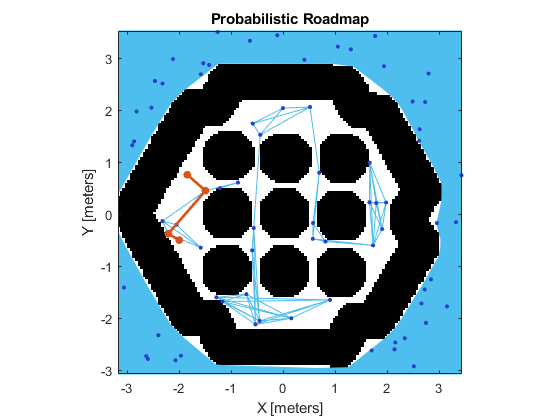


odomSub = rossubscriber('/odom');
odomMsg = receive(odomSub);

[x_odom, y_odom, ~] = OdometryMsg2Pose(odomMsg);
[x_goal, y_goal, ~] = PoseStampedMsg2Pose(navGoalMsg);

turtle_roadmap_inflated = mobileRobotPRM(turtle_map, 1000);
start_loc_turtle = [x_odom y_odom];
goal_loc_turtle = [x_goal y_goal];
turtle_path_inflated = findpath(turtle_roadmap_inflated, start_loc_turtle, goal_loc_turtle);
show(turtle_roadmap_inflated)
ax = gca;
ax.XLim = [-3 3];
ax.YLim = [-3 3];

### Rapidly Exploring Random Tree Planner

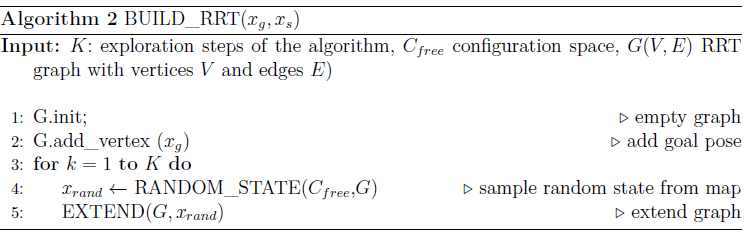

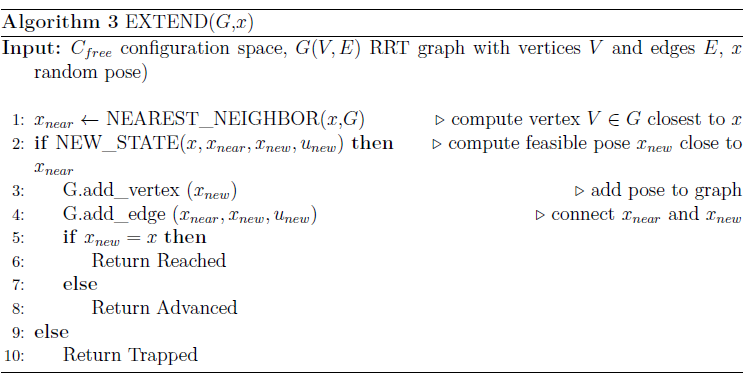

13) Plan a path for a unicycle kinematics ($\texttt{stateSpaceSE2}$) with the RRT algorithm for the complex map with start and goal pose $$x_i=[2 \; 1 \; \pi/2]$$ and $$x_f = [22 \; 18 \; \pi/2]$$. Visualize the path and the tree using the helper function ${\tt displayAndPlotPlanningResult}$.

number of iterations=1217
total pathlength=53


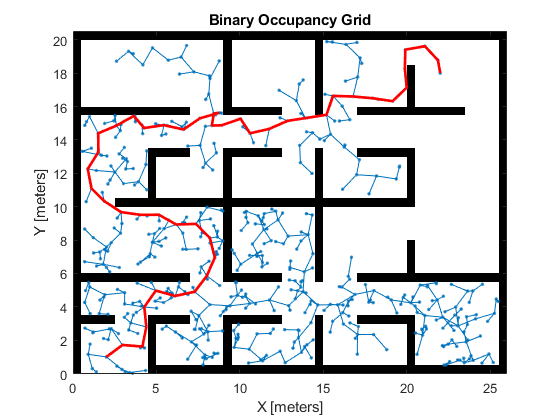

map_complex = binaryOccupancyMap(complexMap, 2);
stateSpace = stateSpaceSE2;
start_pose = [2 1 pi/2];
goal_pose = [22 18 pi/2];

stateSpace.StateBounds = [map_complex.XWorldLimits;...
                          map_complex.YWorldLimits;...
                          [-pi pi]];

stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map_complex;
stateValidator.ValidationDistance = 0.01;
planner = plannerRRT(stateSpace, stateValidator);
planner.MaxIterations = 10000;
planner.MaxConnectionDistance = 1.2;
[pathObj, solnInfo] = planner.plan(start_pose, goal_pose);
displayAndPlotPlanningResult(pathObj, solnInfo, map_complex)

14) Plan a path for a Dubins and Reeds-Shepp vehicle with minimum turning radius $$r_{min}=2.0$$ with the RRT algorithm for the complex map with start and goal pose $$x_i=[2 \; 1 \; \pi/2]$$ and $$x_f = [22 \; 18 \; \pi/2]$$. It is advisable to use a Drop Down control field in the Live Editor code to select the planner and the state space model from a drop down list of options.

Since the $\texttt{stateSpaceSE2}$ model does not possess the property $\texttt{MinTurningRadius}$ do the assignment only for the Dubins and ReedsShepp state space model.

stateSpace = stateSpaceReedsShepp;

start_pose = [2 1 pi/2];
goal_pose = [22 18 pi/2];

map_complex = binaryOccupancyMap(complexMap, 2);

stateSpace.StateBounds = [map_complex.XWorldLimits;...
                          map_complex.YWorldLimits;...
                          [-pi pi]];
stateSpace.MinTurningRadius = 2.0;

stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map_complex;
stateValidator.ValidationDistance = 0.01;
planner = plannerRRT(stateSpace, stateValidator);
planner.MaxIterations = 10000;
planner.MaxConnectionDistance = 1.2;
[pathObj, solnInfo] = planner.plan(start_pose, goal_pose);

15) Visualize the path and the tree. 

number of iterations=2191
total pathlength=65


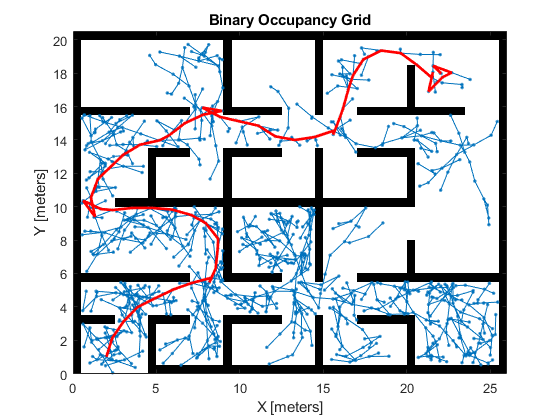

displayAndPlotPlanningResult(pathObj, solnInfo, map_complex)

16) Report the number of iterations and the path length for the three kinematic models according to the table below.

resultTable = table({'RRT';'RRT';'RRT'}, {'unicycle';'Dubins';'ReedsShepp'}, zeros(3,1), zeros(3,1), 'VariableNames',{'planner', 'kinematics', '#iterations', 'path length'});
resultTable{1, '#iterations'} = 1655 ;% RRT + unicycle
resultTable{1, 'path length'} = 48 ;% RRT + unicycle
resultTable{2, '#iterations'} = 0 ;% RRT + Dubins => NO PATH FOUND
resultTable{2, 'path length'} = 0 ;% RRT + Dubins => NO PATH FOUND
resultTable{3, '#iterations'} = 2741 ;% RRT + Reeds-Shepp
resultTable{3, 'path length'} = 57 ;% RRT + Reeds-Shepp
disp(resultTable);

    planner      kinematics      #iterations    path length
    _______    ______________    ___________    ___________

    {'RRT'}    {'unicycle'  }       1655            48     
    {'RRT'}    {'Dubins'    }          0             0     
    {'RRT'}    {'ReedsShepp'}       2741            57     



17) Investigate the effect of the planner property $\texttt{MaxConnectionDistance}$ on the number of iterations as well as the path length. It is advisable to use a Numeric Slider control field in the Live Editor to easily explore different values for $\texttt{MaxConnectionDistance}$.

% StateSpaceE2
% MaxConnectionDistance: 0.9; => number of iterations: 746; path length: 46;
% MaxConnectionDistance: 1.0; => number of iterations: 312; path length: 40;
% MaxConnectionDistance: 1.1; => number of iterations: 630; path length: 42;
% MaxConnectionDistance: 1.2; => number of iterations: 1217; path length: 53;

% Dubins
% MaxConnectionDistance: 0.9; => number of iterations: NaN; path length: NaN; 
% MaxConnectionDistance: 1.0; => number of iterations: NaN; path length: NaN; 
% MaxConnectionDistance: 1.1; => number of iterations: NaN; path length: NaN;
% MaxConnectionDistance: 1.2; => number of iterations: NaN; path length: NaN;

% ReedsShepp
% MaxConnectionDistance: 0.9; => number of iterations: 2322; path length: 44;
% MaxConnectionDistance: 1.0; => number of iterations: 1488; path length: 48;
% MaxConnectionDistance: 1.1; => number of iterations: 2657; path length: 53;
% MaxConnectionDistance: 1.2; => number of iterations: 2191; path length: 65;

% Path length fluctuates but almost always the nummber of iterations increase
% if the property MaxConnectionDistance increases.

### Bidirectional Rapidly Exploring Random Trees

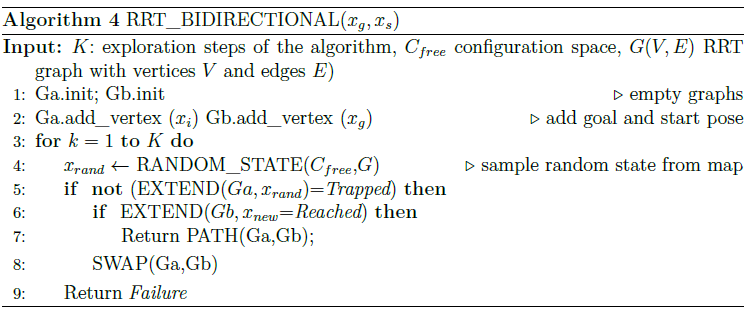

18) Plan a path for a unicycle kinematics ($\texttt{stateSpaceSE2}$) with the BiRRT algorithm for the complex map with start and goal pose $$x_i=[2\; 1\; \pi/2]$$ and $$x_f = [22\; 18\; \pi/2]$$.

map_complex = binaryOccupancyMap(complexMap, 2);
stateSpace = stateSpaceSE2;
start_pose = [2 1 pi/2];
goal_pose = [22 18 pi/2];

stateSpace.StateBounds = [map_complex.XWorldLimits;...
                          map_complex.YWorldLimits;...
                          [-pi pi]];

stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map_complex;
stateValidator.ValidationDistance = 0.01;
planner = plannerBiRRT(stateSpace, stateValidator);
planner.MaxIterations = 10000;
planner.MaxConnectionDistance = 0.8;
planner.EnableConnectHeuristic = true;
[pathObj, solnInfo] = planner.plan(start_pose, goal_pose);

19) Visualize the path and the two trees. For this, extend the helper function ${\tt displayAndPlotPlanningResult}$ accordingly.

number of iterations=234
total pathlength=36


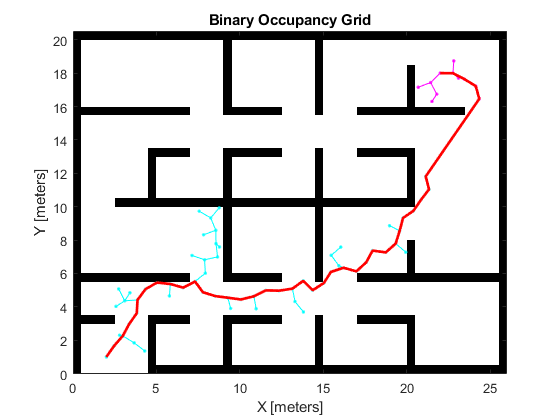

displayAndPlotPlanningResult(pathObj, solnInfo, map_complex)

20) Plan a path for a Dubins and Reeds-Shepp vehicle ($$r_{min}=2.0$$) with the BiRRT algorithm for the complex map with start and goal pose $$x_i=[2\; 1\; \pi/2]$$ and $$x_f = [22\; 18\; \pi/2]$$.

number of iterations=3991
total pathlength=35


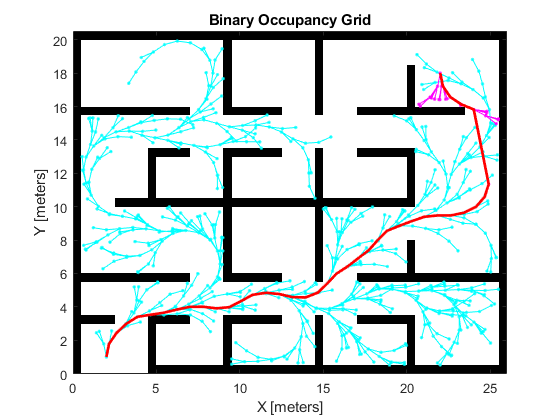

map_complex = binaryOccupancyMap(complexMap, 2);
stateSpace = stateSpaceDubins;
start_pose = [2 1 pi/2];
goal_pose = [22 18 pi/2];

stateSpace.StateBounds = [map_complex.XWorldLimits;...
                          map_complex.YWorldLimits;...
                          [-pi pi]];
stateSpace.MinTurningRadius = 2.0;

stateValidator = validatorOccupancyMap(stateSpace);
stateValidator.Map = map_complex;
stateValidator.ValidationDistance = 0.01;
planner = plannerBiRRT(stateSpace, stateValidator);
planner.MaxIterations = 10000;
planner.MaxConnectionDistance = 0.8;
planner.EnableConnectHeuristic = true;
[pathObj, solnInfo] = planner.plan(start_pose, goal_pose);
displayAndPlotPlanningResult(pathObj, solnInfo, map_complex)

21) Report the number of iterations and the path length for the three kinematic models in the table below.

resultTable = table({'RRT';'RRT';'RRT';'BiRRT';'BiRRT';'BiRRT'}, {'unicycle';'Dubins';'ReedsShepp';'unicycle';'Dubins';'ReedsShepp'}, zeros(6,1), zeros(6,1), 'VariableNames',{'planner', 'kinematics', '#iterations', 'path length'});
resultTable{1, '#iterations'} = 1655 ;% RRT + unicycle
resultTable{1, 'path length'} = 48 ;% RRT + unicycle
resultTable{2, '#iterations'} = 0 ;% RRT + Dubins => NO PATH FOUND
resultTable{2, 'path length'} = 0 ;% RRT + Dubins => NO PATH FOUND
resultTable{3, '#iterations'} = 2741 ;% RRT + Reeds-Shepp
resultTable{3, 'path length'} = 57 ;% RRT + Reeds-Shepp
resultTable{4, '#iterations'} = 314 ;% BiRRT + unicycle
resultTable{4, 'path length'} = 49 ;% BiRRT + unicycle
resultTable{5, '#iterations'} = 1200 ;% BiRRT + Dubins
resultTable{5, 'path length'} = 35 ;% BiRRT + Dubins
resultTable{6, '#iterations'} = 1050 ;% BiRRT + Reeds-Shepp
resultTable{6, 'path length'} = 53 ;% BiRRT + Reeds-Shepp
disp(resultTable);

     planner       kinematics      #iterations    path length
    _________    ______________    ___________    ___________

    {'RRT'  }    {'unicycle'  }       1655            48     
    {'RRT'  }    {'Dubins'    }          0             0     
    {'RRT'  }    {'ReedsShepp'}       2741            57     
    {'BiRRT'}    {'unicycle'  }        314            49     
    {'BiRRT'}    {'Dubins'    }       1200            35     
    {'BiRRT'}    {'ReedsShepp'}       1050            53     



22) Investigate the effect of the flag $\texttt{EnableConnectHeuristic}$ on the number of iterations as well as the path length.

% All results are for planner.MaxConnectionDistance = 0.8;

% StateSpaceE2
% EnableConnectHeuristic: true; => number of iterations: 450; path length: 45;
% EnableConnectHeuristic: false; => number of iterations: 539; path length: 47;

% Dubins
% EnableConnectHeuristic: true; => number of iterations: 3991; path length: 35;
% EnableConnectHeuristic: false; => number of iterations: NaN; path length: NaN;

% ReedsShepp
% EnableConnectHeuristic: true; => number of iterations: 1050; path length: 53;
% EnableConnectHeuristic: false; => number of iterations: 1638; path length: 48;

% Path length deviates but almost always the nummber of iterations increase
% if the property EnableConnectHeuristic is true.

23) (Optional) Investigate the performance of ther RRT* planning algorithm (${\tt plannerRRTStar}$).

# Helper Functions

function [ x, y, theta ] = OdometryMsg2Pose( odomMsg )
    % convert odometry message to vector
    x=odomMsg.Pose.Pose.Position.X;
    y=odomMsg.Pose.Pose.Position.Y;
    eul=quat2eul([odomMsg.Pose.Pose.Orientation.W odomMsg.Pose.Pose.Orientation.X  odomMsg.Pose.Pose.Orientation.Y odomMsg.Pose.Pose.Orientation.Z]);
    theta=eul(1);
end

function [ x, y, theta ] = PoseStampedMsg2Pose( poseMsg )
    % convert odometry message to vector
    x=poseMsg.Pose.Position.X;
    y=poseMsg.Pose.Position.Y;
    eul=quat2eul([poseMsg.Pose.Orientation.W poseMsg.Pose.Orientation.X  poseMsg.Pose.Orientation.Y poseMsg.Pose.Orientation.Z]);
    theta=eul(1);
end

function displayAndPlotPlanningResult(pathObj, solnInfo, map)
    if ~solnInfo.IsPathFound
        disp('no path found');
    else
        disp(['number of iterations=' num2str(solnInfo.NumIterations)]);
        disp(['total pathlength=' num2str(pathObj.pathLength(),2)]);
        
        % show map
        show(map);
        hold on
        
        % plot tree data
        plot(solnInfo.StartTreeData(:,1),solnInfo.StartTreeData(:,2),'.c-'); % tree expansion
        plot(solnInfo.GoalTreeData(:,1),solnInfo.GoalTreeData(:,2),'.m-');
        
        % plot states
        plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2); % draw path
                
        hold off;
    end
end